Authors: Darpa MINT TA1 modeling team

FREE RUN

Last version: 12/01/2023

This script calculates simulated IPF maps using the line-based Voronoi approach. Important parameters are:

- The number of generating lines - N

- The average for the inverse Gaussian distribution - μ

- The shape factor for the inverse Gaussian distribution - λ

- The seed used for random number generation - seedNumber

- The sizes of the simulation domain LX and LY (for LS surface 1000 x 700)

Run time is about 180s on a Intel Core i5-7200U 2.5GHZ laptop with 8GB DDR4 memory

Toolboxes in use:

- matlab

- image_toolbox

- statistics_toolbox

clear all
close all
clf
%
tic
%

First specify the variables and parameters. 

N=1400;     % number of generating lines
mu=46;      % mu parameter in Inverse Gaussian distribution
lambda=6;   % lambda parameter in Inverse Gaussian distribution
seedNumber = 717;    % seed number
LX=1000;    % map size in X direction
LY=700;    % map size in Y direction

Calculate the sim IPF map using the AA5456_Unit1_GrainGenerator_Sim unit: 

C=GrainGenerator_Sim(N,mu,lambda,seedNumber,LX,LY);

Plot resulting image and save the image and grain structure: 

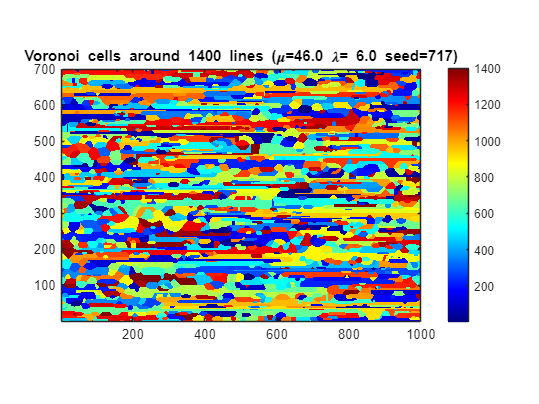

f = figure(1);              % creates figure object
imagesc(C),colormap(jet),colorbar,axis('image');
set(gca,'YDir','normal')
title(sprintf('Voronoi cells around %d lines (\\mu=%4.1f \\lambda=%4.1f seed=%d)',N,mu,lambda,seedNumber));

Fname1 = sprintf('imageGrains_lines%d_mu%d_lambda%d_seed%d_LX%d_LY%d.jpg',N,mu,lambda,seedNumber,LX,LY);
Fname2 = sprintf('dataGrains_lines%d_mu%d_lambda%d_seed%d_LX%d_LY%d.txt',N,mu,lambda,seedNumber,LX,LY);
exportgraphics(f,Fname1,'Resolution',600);   % saves figure

writematrix(C,Fname2);                       % saves data

toc

Elapsed time is 43.372225 seconds.
